clearvars;
syms x m w h
assume(m > 0)
assume(w > 0)
assume(h > 0)

alpha = (m*w/(pi*h))^(1/4);
psi0 = alpha*exp(-m*w*x^2/(2*h))

$$psi0 = {\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}\,{\left(\frac{m\,w}{h\,\pi }\right)}^{1/4}$$

aplus = @(psi) (m*w*x*psi - h*diff(psi,x))/sqrt(2*m*w*h);
psi1 = simplify(aplus(psi0))

$$psi1 = \frac{\sqrt{2}\,m^{3/4}\,w^{3/4}\,x\,{\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}}{h^{3/4}\,\pi^{1/4}}$$

psi2 = simplify(aplus(psi1)/sqrt(2))

$$psi2 = -\frac{\sqrt{2}\,m^{1/4}\,w^{1/4}\,{\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}\,\left(h-2\,m\,w\,x^{2}\right)}{2\,h^{5/4}\,\pi^{1/4}}$$


p0 = subs(psi0,[m w h],[1 1 1]);
p1 = subs(psi1,[m w h],[1 1 1]);
p2 = subs(psi2,[m w h],[1 1 1]);

figure
hold on
range = [-4 4]

range =     -4     4


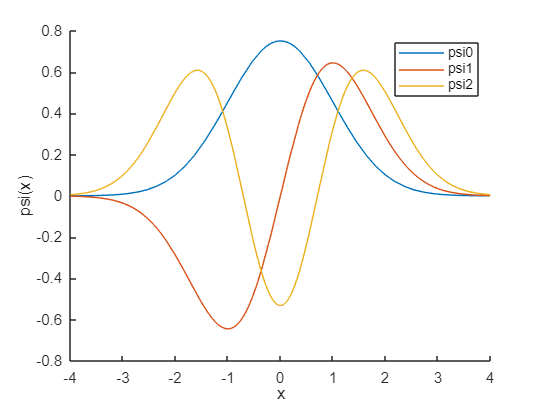

fplot(p0,range)
fplot(p1,range)
fplot(p2,range)
xlabel('x')
ylabel('psi(x)')
legend('psi0','psi1','psi2')
hold off

Orth1 = simplify(int(conj(psi0)*psi1,x,-inf,inf))

$$Orth1 = 0$$

Orth2 = simplify(int(conj(psi0)*psi2,x,-inf,inf))

$$Orth2 = 0$$

Orth3 = simplify(int(conj(psi1)*psi2,x,-inf,inf))

$$Orth3 = 0$$

2)

clearvars;
syms x m w h
assume(m > 0)
assume(w > 0)
assume(h > 0)

alpha = (m*w/(pi*h))^(1/4);
psi0 = alpha*exp(-m*w*x^2/(2*h));
aplus = @(psi) (m*w*x*psi - h*diff(psi,x))/sqrt(2*m*w*h);
psi1 = simplify(aplus(psi0));
x0 = simplify(int(conj(psi0)*x*psi0,x,-inf,inf))

$$x0 = 0$$

p0 = simplify(int(conj(psi0)*(-1i*h*diff(psi0,x)),x,-inf,inf))

$$p0 = 0$$

x20 = simplify(int(conj(psi0)*x^2*psi0,x,-inf,inf))

$$x20 = \frac{h}{2\,m\,w}$$

p20 = simplify(int(conj(psi0)*(-h^2*diff(psi0,x,2)),x,-inf,inf))

$$p20 = \frac{h\,m\,w}{2}$$

x1 = simplify(int(conj(psi1)*x*psi1,x,-inf,inf))

$$x1 = 0$$

p1 = simplify(int(conj(psi1)*(-1i*h*diff(psi1,x)),x,-inf,inf))

$$p1 = 0$$

x21 = simplify(int(conj(psi1)*x^2*psi1,x,-inf,inf))

$$x21 = \frac{3\,h}{2\,m\,w}$$

p21 = simplify(int(conj(psi1)*(-h^2*diff(psi1,x,2)),x,-inf,inf))

$$p21 = \frac{3\,h\,m\,w}{2}$$

sigmax0 = simplify(sqrt(x20-x0^2));
sigmap0 = simplify(sqrt(p20-p0^2));
uncertainty0 = simplify(sigmax0*sigmap0)

$$uncertainty0 = \frac{h}{2}$$

sigmax1 = simplify(sqrt(x21-x1^2));
sigmap1 = simplify(sqrt(p21-p1^2));
uncertainty1 = simplify(sigmax1*sigmap1)

$$uncertainty1 = \frac{3\,h}{2}$$

T0 = simplify(p20/(2*m))

$$T0 = \frac{h\,w}{4}$$

V0 = simplify((m*w^2*x20)/2)

$$V0 = \frac{h\,w}{4}$$

E0 = simplify(T0+V0)

$$E0 = \frac{h\,w}{2}$$

T1 = simplify(p21/(2*m))

$$T1 = \frac{3\,h\,w}{4}$$

V1 = simplify((m*w^2*x21)/2)

$$V1 = \frac{3\,h\,w}{4}$$

E1 = simplify(T1+V1)

$$E1 = \frac{3\,h\,w}{2}$$

3) 

clearvars;
syms n m w h
assume(n >= 0)
assume(n,'integer')
assume(m > 0)
assume(w > 0)
assume(h > 0)
ap = 0;
am = 0;
ap2 = 0;
am2 = 0;
apam = n;
amap = n+1;

x = simplify(sqrt(h/(2*m*w))*(ap+am))

$$x = 0$$

p = simplify(1i*sqrt(m*w*h/2)*(ap-am))

$$p = 0$$

x2 = simplify((h/(2*m*w))*(ap2+apam+amap+am2))

$$x2 = \frac{h\,\left(2\,n+1\right)}{2\,m\,w}$$

p2 = simplify((-m*w*h/2)*(ap2-apam-amap+am2))

$$p2 = \frac{h\,m\,w\,\left(2\,n+1\right)}{2}$$

T = simplify(p2/(2*m))

$$T = \frac{h\,w\,\left(2\,n+1\right)}{4}$$

sigmax = simplify(sqrt(x2-x^2))

$$sigmax = \frac{\sqrt{h}\,\sqrt{n+\frac{1}{2}}}{\sqrt{m}\,\sqrt{w}}$$

sigmap = simplify(sqrt(p2-p^2))

$$sigmap = \sqrt{h}\,\sqrt{m}\,\sqrt{w}\,\sqrt{n+\frac{1}{2}}$$

uncertainty = simplify(sigmax*sigmap)

$$uncertainty = h\,\left(n+\frac{1}{2}\right)$$

check = simplify(uncertainty-h/2)

$$check = h\,n$$